## Project 2: Calculating Values at Risk

### 1.

Let the log returns $X$ be given by $X_t =\log \left(V_t \right)-\log \left(V_{t-1} \right)$. Let $F_{X_t } =P\left(X_t \le \cdot \left|\left(X_s ,V_s ,s<t\right)\right.\right)$ be the cumulative distribution function of $X_t$ given all information up to time $t-1$. Show that


$${\textrm{VaR}}_t =V_{t-1} \left(e^{F_{X_t }^{-1} \left(p\right)} -1\right)$$



$$p=P\left(V_t -V_{t-1} \le {\textrm{VaR}}_t \;\left|\;\left(V_s ,s<t\right)\right.\right)$$



$$F_{X_t }^{-1} \left(p\right)=\left\lbrace x:P\left(X_t \le x\;\left|\;\left(X_s ,V_s ,s<t\right)\right.\right)=p\right\rbrace$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left\lbrace x:P\left(X_t \le x\;\left|\;\left(X_s ,V_s ,s<t\right)\right.\right)=P\left(V_t -V_{t-1} \le {\textrm{VaR}}_t \;\left|\;\left(V_s ,s<t\right.\right.\right)\right\rbrace$$


Above, $\left\lbrace x:y\right\rbrace$is read as "$x$ such that $y$ holds"


$$\begin{array}{l}
X_t =\log \left(V_t \right)-\log \left(V_{t-1} \right)\\
\;\;\;\;=\log \left(\frac{V_t }{V_{t-1} }\right)\\
e^{X_t } =\frac{V_t }{V_{t-1} }\\
V_{t-1} \left(e^{X_t } -1\right)=V_t -V_{t-1} 
\end{array}$$



$$\begin{array}{l}
P\left(V_t -V_{t-1} \le {\textrm{VaR}}_t \;\left|\;\left(V_s ,s<t\right)\right.\right)=P\left(V_{t-1} \left(e^{X_t } -1\right)\le {\textrm{VaR}}_t \;\left|\;\left(V_s ,s<t\right)\right.\right)=P\left(e^{X_t } \le \frac{{\textrm{VaR}}_t }{V_{t-1} }+1\left|\;\left(V_s ,s<t\right)\right.\right)\\
=P\left(X_t \le \log \left(\frac{{\textrm{VaR}}_t }{V_{t-1} }+1\right)\left|\;\left(V_s ,s<t\right)\right.\right)
\end{array}$$



$$\begin{array}{l}
F_{X_t }^{-1} \left(p\right)=\left\lbrace x:P\left(X_t \le x\;\left|\;\left(X_s ,V_s ,s<t\right)\right.\right)=P\left(X_t \le \log \left(\frac{{\textrm{VaR}}_t }{V_{t-1} }+1\right)\left|\;\left(V_s ,s<t\right)\right.\right)\right\rbrace \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left\lbrace x:x=\log \left(\frac{{\textrm{VaR}}_t }{V_{t-1} }+1\right)\right\rbrace =\log \left(\frac{{\textrm{VaR}}_t }{V_{t-1} }+1\right)
\end{array}$$



$$\begin{array}{l}
F_{X_t }^{-1} \left(p\right)=\log \left(\frac{{\textrm{VaR}}_t }{V_{t-1} }+1\right)\\
e^{F_{X_t }^{-1} \left(p\right)} =\frac{{\textrm{VaR}}_t }{V_{t-1} }+1\\
{\textrm{VaR}}_t =V_{t-1} \left(e^{F_{X_t }^{-1} \left(p\right)} -1\right)
\end{array}$$


### 2.

Plot the (sample) autocorrelation and partial autocorrelation functions of X for lags h = 0,...,50

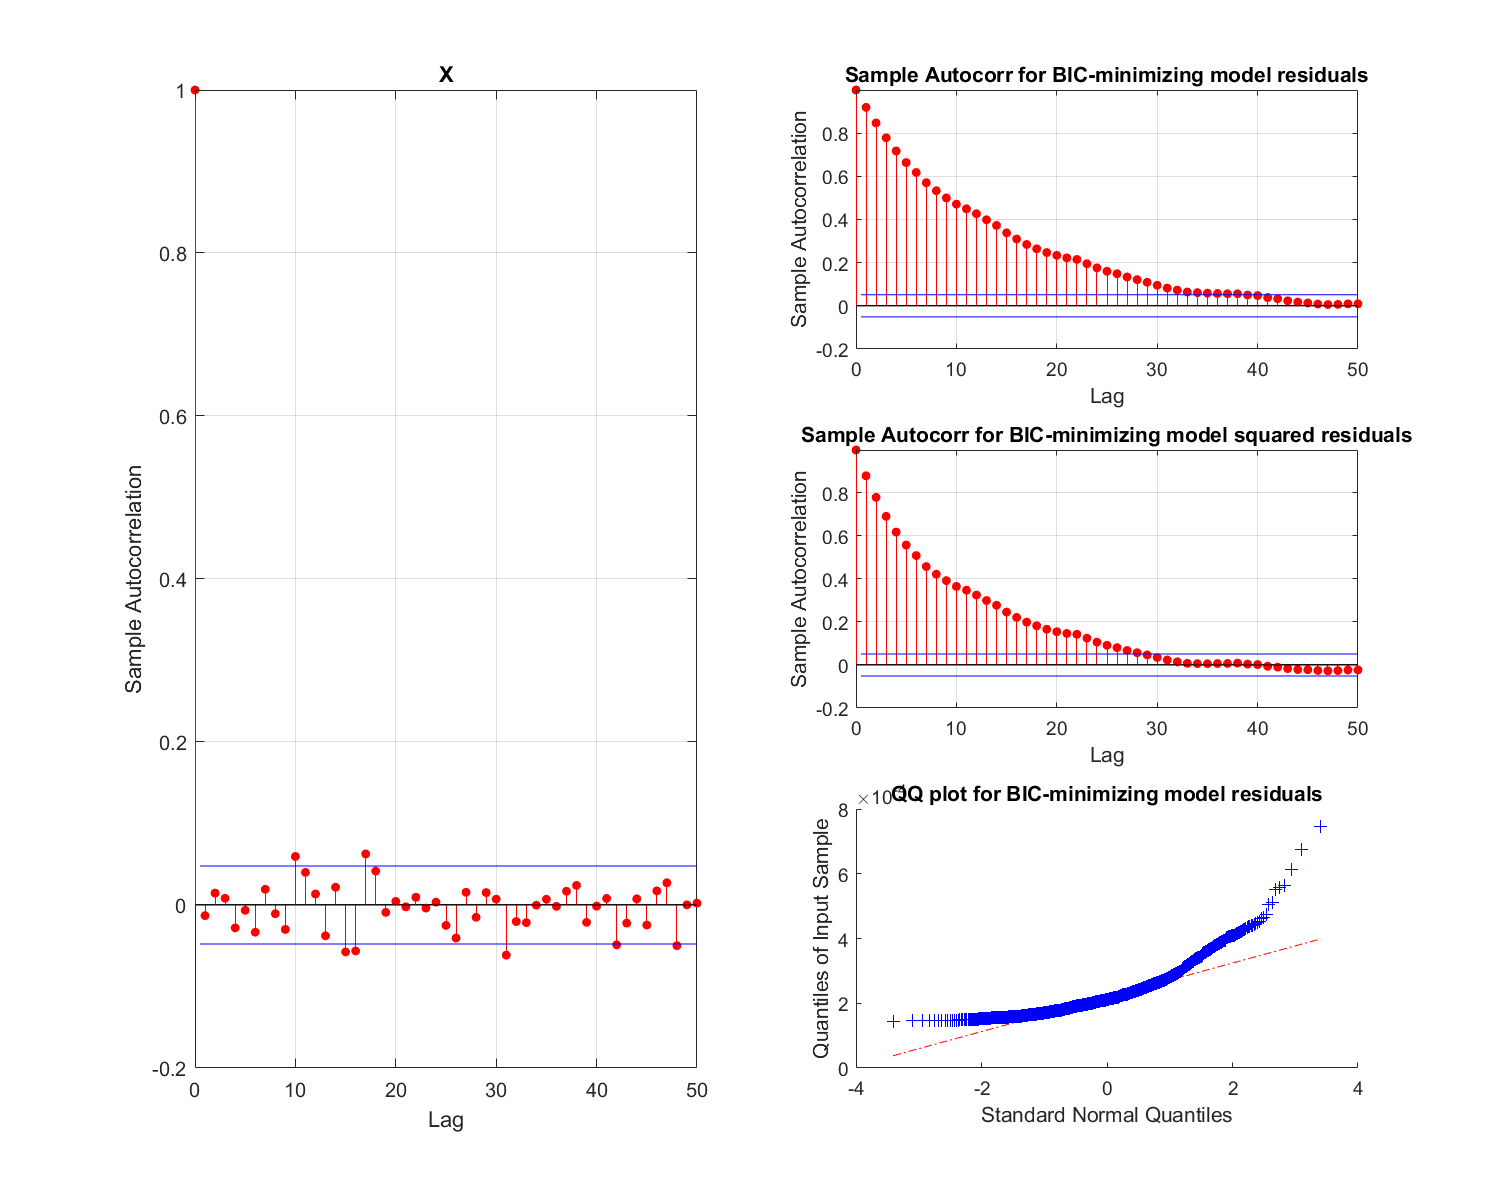

V = readtable('dat_intel.csv');
X = log(V.Close(2:end)) - log(V.Close(1:end-1));

subplot(1,2,1)
autocorr(X,'NumLags',50)
title('X')
ylim([-.2, 1])
xlim([0, 50])

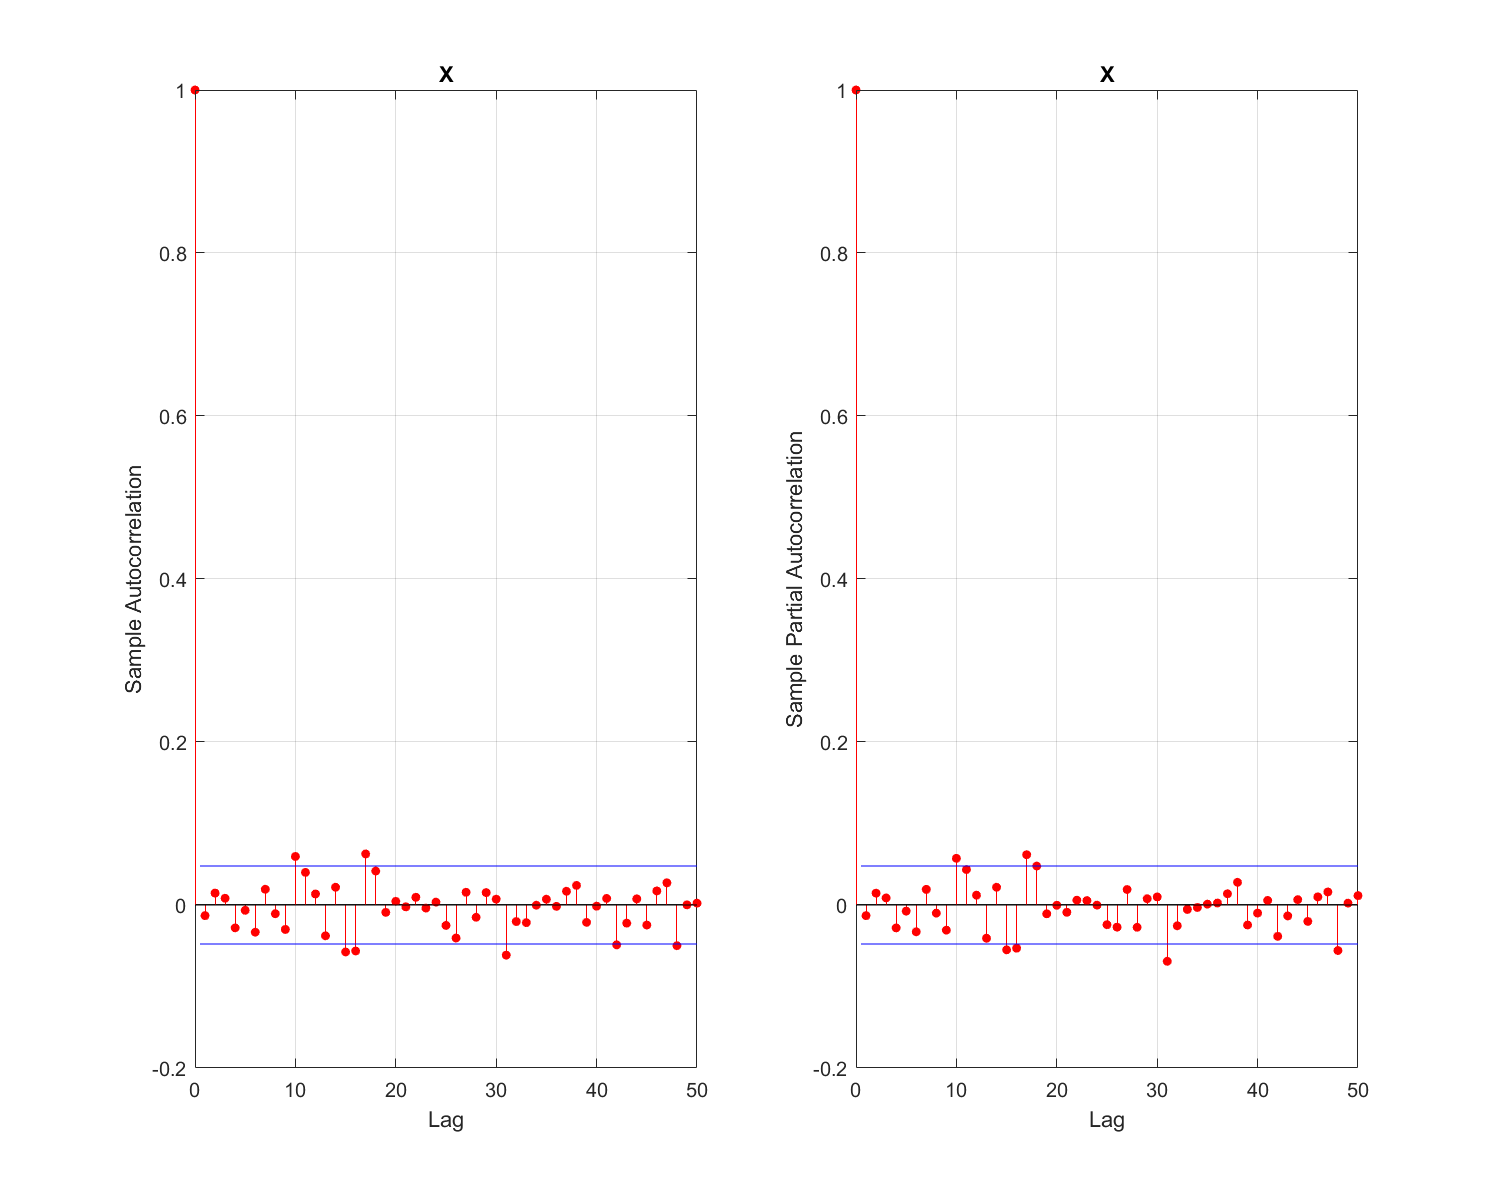


subplot(1,2,2)
parcorr(X,'NumLags',50)
title('X')
ylim([-.2, 1])
xlim([0, 50])

Then, do a Ljung–Box test with h = 50 for X

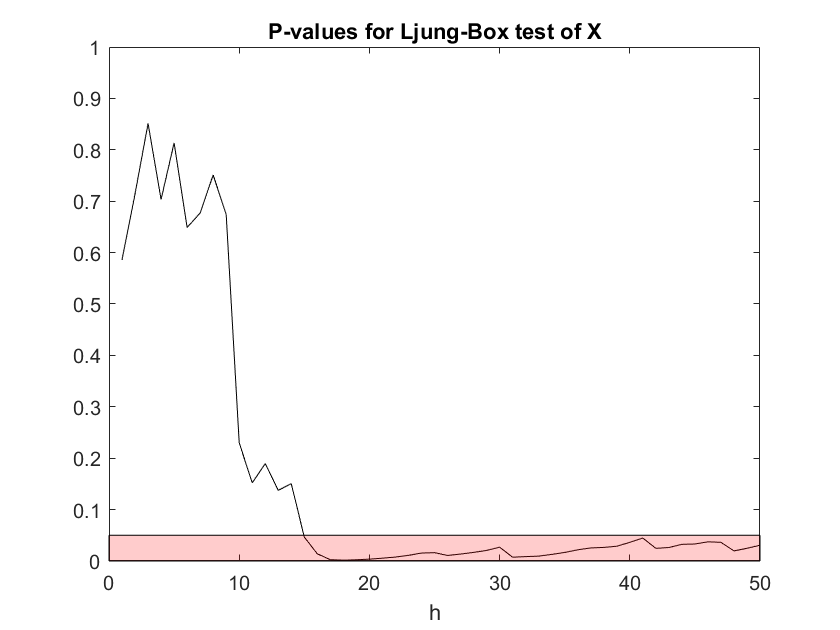

alpha = .05;
lags = 1:50;
close all
[h, pValues, stat, cValue] = lbqtest(X, 'lags', lags);

p = plot(lags, pValues, 'k');
tmp_x = [p.Parent.XLim(1) p.Parent.XLim(1) p.Parent.XLim(2) p.Parent.XLim(2)];
tmp_y = [p.Parent.YLim(1) alpha alpha p.Parent.YLim(1)];
patch(tmp_x, tmp_y, 'r', 'facealpha', .2)
ylim([0, 1])
xlim([0,50])
title('P-values for Ljung-Box test of X')
xlabel('h')

if pValues(find(lags==50)) < alpha
    disp('Reject H0 at h=50')
else
    disp('Fail to reject H0 at h=50')
end

Reject H0 at h=50


Repeat these two steps with the squared returns $X^2$. We start with the (sample) autocorrelation and partial autocorrelation functions of $X^2$ for lags h = 0,...,50

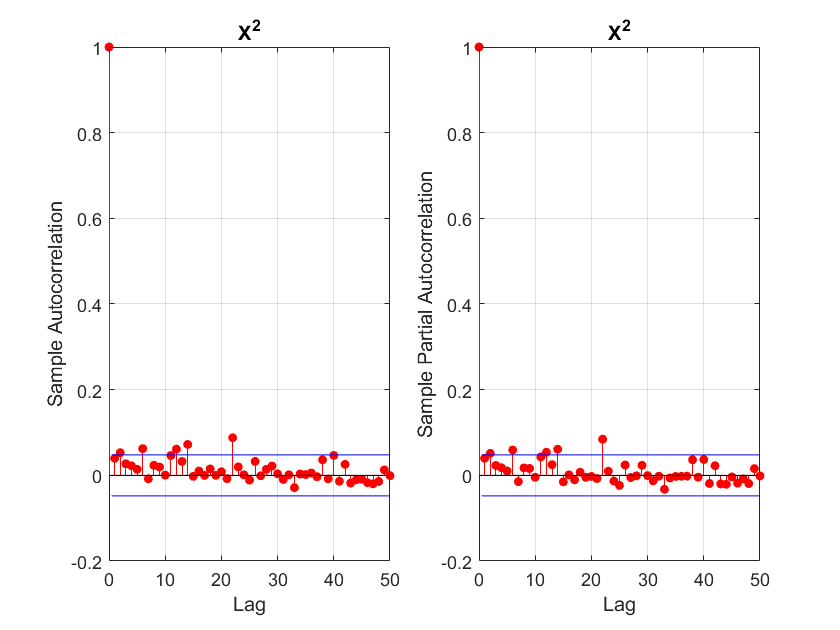

subplot(1,2,1)
autocorr(X.^2,'NumLags',50)
title('X^2')
ylim([-.2, 1])
xlim([0, 50])
subplot(1,2,2)
parcorr(X.^2,'NumLags',50)
title('X^2')
ylim([-.2, 1])
xlim([0, 50])

do a Ljung–Box test with h = 50 for X^2

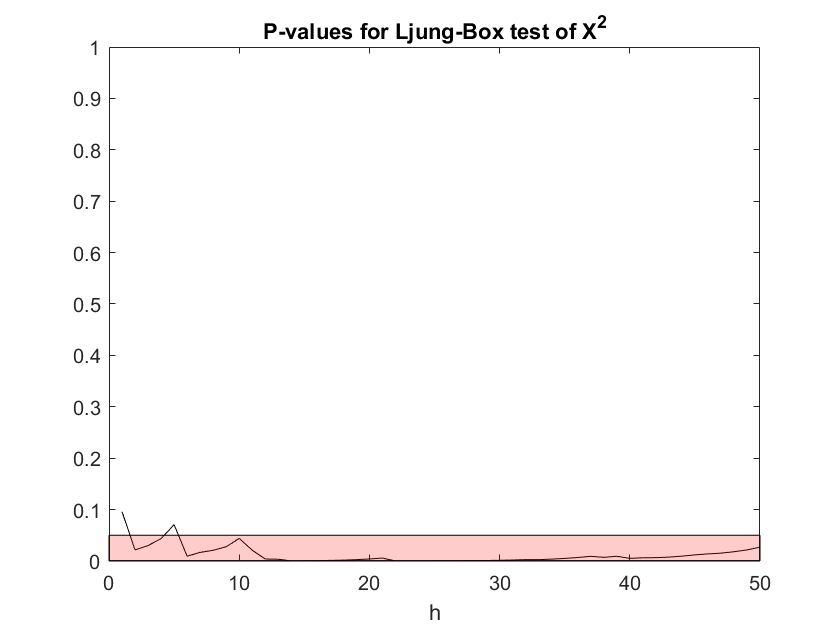

close all
[h, pValues, stat, cValue] = lbqtest(X.^2, 'lags', lags, 'Alpha', alpha);

p = plot(lags, pValues, 'k');
tmp_x = [p.Parent.XLim(1) p.Parent.XLim(1) p.Parent.XLim(2) p.Parent.XLim(2)];
tmp_y = [p.Parent.YLim(1) alpha alpha p.Parent.YLim(1)];

patch(tmp_x, tmp_y, 'r', 'facealpha', .2)
ylim([0, 1])
title('P-values for Ljung-Box test of X^2')
xlabel('h')

if pValues(find(lags==50)) < alpha
    disp('Reject H0 at h=50')
else
    disp('Fail to reject H0 at h=50')
end

Reject H0 at h=50


#### Discussion

Both $X$ and $X^2$ (the squared returns) have outliers on the autocorrelation function plots. They are not very large, but significant enough to be above the 95% confidence interval plotted at several lags, indicating that the series is not entirely white noise. For both $X$ and $X^2$ we reject the Ljung-Box null hypotheses that $X$ and $X^2$ are realizations of $\textrm{IID}\left(\mu \;,\sigma {\;}^2 \right)$ at the 5% level for $h=50$. 

### 3)

Now split the time series $X$ into a training set ($X_t$ , t = 2,...,1526) and a test set ($X_t$ , t = 1527, . . . , 1751).

trainX = X(2:1526);
testX = X(1527:1750);

#### Gaussian distribution

For all values of p and q in the range 0, 1, . . . , 15 and such that p+q > 0 and p ≥ q, fit an ARMA(p, q) process with Gaussian noise to the square returns obtained from the training data and compute the BIC and the AICC (this will take a couple of minutes). Which models minimize the two information criteria? 

i=1;
clear pq mdl logL numParam WN_variance_MLE
pq = [];
for p = 0:15
    for q = 0:p
        if p+q>0 && p>=q
            mdl(i) = arima(p, 0, q);
            pq = [pq,  [p; q]];
            i = i + 1;
        end
    end
end
p = pq(1,:);
q = pq(2,:);

https://se.mathworks.com/help/econ/aicbic.html

Options = optimoptions(@fmincon,'ConstraintTolerance',1e-7,'Algorithm','interior-point');
for i = 1:length(mdl)
    [EstMdl, ~, logL(i)] = estimate(mdl(i),trainX.^2,'Display','off','Options',Options);
    results = summarize(EstMdl);
%     numParam(i) = results.NumEstimatedParameters; % this includes the zero-valued params
    numParam(i) = sum(results.Table.Value ~= 0); % = M from hints
    WN_variance_MLE(i) = results.VarianceTable.Value; % maximum likelihood estimate of white noise variance
end

Note! ic part did not work when using R2020a. Tested and worked on R2021a.

AICC = calculateAICC(length(trainX), numParam, logL); % both defined at end of file
% BIC = calculateBIC(length(trainX), p, q, WN_variance_MLE, trainX.^2, numParam, 'M');
BIC = calculateBIC(length(trainX), p, q, WN_variance_MLE, trainX.^2, numParam, 'pq');
disp(["Model which minimizes [BD]'s AICC:" mdl(find(AICC==min(AICC))).Description; "Model which minimizes [BD]'s BIC:" mdl(find(BIC==min(BIC))).Description])

    "Model which minimizes [BD]'s AICC:"    "ARIMA(2,0,0) Model (Gaussian Distribution)"
    "Model which minimizes [BD]'s BIC:"     "ARIMA(3,0,1) Model (Gaussian Distribution)"



[aic, bic, ic] = aicbic(logL, numParam, length(trainX));
[~,minIdx] = structfun(@min,ic);
minIdxChosen = [minIdx(2:3)];
disp(["Model which minimizes aicbic's AICC:" mdl(minIdxChosen(2)).Description; "Model which minimizes aicbic's BIC:" mdl(minIdxChosen(1)).Description])

    "Model which minimizes aicbic's AICC:"    "ARIMA(2,0,0) Model (Gaussian Distribution)"
    "Model which minimizes aicbic's BIC:"     "ARIMA(1,0,0) Model (Gaussian Distribution)"



bestmdl_Gauss_AICC = mdl(find(AICC==min(AICC)));
bestmdl_Gauss_BIC = mdl(find(BIC==min(BIC)));
% bestmdl_Gauss_AICC = mdl(minIdxChosen(2));
% bestmdl_Gauss_BIC = mdl(minIdxChosen(1));

According to hints and notes: 

*•Compute the BIC and AICC using the formulas given in Methods 3.2.22 and 3.2.23 of the lecture notes. Think of replacing the quantity p + q + 1 by the number M of (non-zero) parameters actually estimated by the algorithm. *

So using aicbic might not be the way they want us to get it. This could maybe be used if our own formulas is correct or not.

#### Student’s *t *distribution

*@*Matthias Lecture 7a 57:30 he talks about using a *conditional MLE* for *t*-distribution. I'm only that far so idk if youre aware, or what that means exactly

i = 1;
clear pq mdl logL numParam WN_variance_MLE
pq = [];
for p = 0:15
    for q = 0:p
        if p+q>0 && p>=q
            mdl(i) = arima(p,0,q); 
            mdl(i).Distribution="t";
            pq = [pq,  [p; q]];
            i = i + 1;
        end
    end
end
p = pq(1,:);
q = pq(2,:);

Options = optimoptions(@fmincon,'ConstraintTolerance',1e-7,'Algorithm','interior-point');
for i = 1:size(mdl,2)
    try
        [EstMdl,~,logL(i)] = estimate(mdl(i),trainX.^2,'Display','off','Options', Options);
        results = summarize(EstMdl);
%         numParam(i) = results.NumEstimatedParameters;
        numParam(i) = sum(results.Table.Value ~= 0); % = M from hints
        WN_variance_MLE(i) = results.VarianceTable.Value; % maximum likelihood estimate of white noise variance
    catch
        disp("error")
        disp(mdl(i).Description)
        disp("")
    end
end

AICC = calculateAICC(length(trainX), numParam, logL); % both defined at end of file
BIC = calculateBIC(length(trainX), p, q, WN_variance_MLE, trainX.^2, numParam, 'M');
disp(["Model which minimizes [BD]'s AICC:" mdl(find(AICC==min(AICC))).Description; "Model which minimizes [BD]'s BIC:" mdl(find(BIC==min(BIC))).Description])

    "Model which minimizes [BD]'s AICC:"    "ARIMA(5,0,3) Model (t Distribution)"
    "Model which minimizes [BD]'s BIC:"     "ARIMA(4,0,1) Model (t Distribution)"



[aic, bic, ic] = aicbic(logL, numParam);
[~, minIdx] = structfun(@min, ic);
minIdxChosen = [minIdx(2:3)];
disp(["Model which minimizes aicbic's AICC:" mdl(minIdxChosen(2)).Description; "Model which minimizes aicbic's BIC:" mdl(minIdxChosen(1)).Description])

    "Model which minimizes aicbic's AICC:"    "ARIMA(5,0,3) Model (t Distribution)"
    "Model which minimizes aicbic's BIC:"     "ARIMA(5,0,3) Model (t Distribution)"



bestmdl_t_AICC = mdl(find(AICC==min(AICC)));
bestmdl_t_BIC = mdl(find(BIC==min(BIC)));
% bestmdl_t_AICC = mdl(minIdxChosen(2));
% best_mdl_t_BIC = mdl(minIdxChosen(1));

@Matthias: Not equal here. For AICC it's choosing the min of ic.aic. Note if were sweeping p and q = 0:15, do we expect p=15 and q=14 to be the best model? i would think theyd have us use a generous param sweep

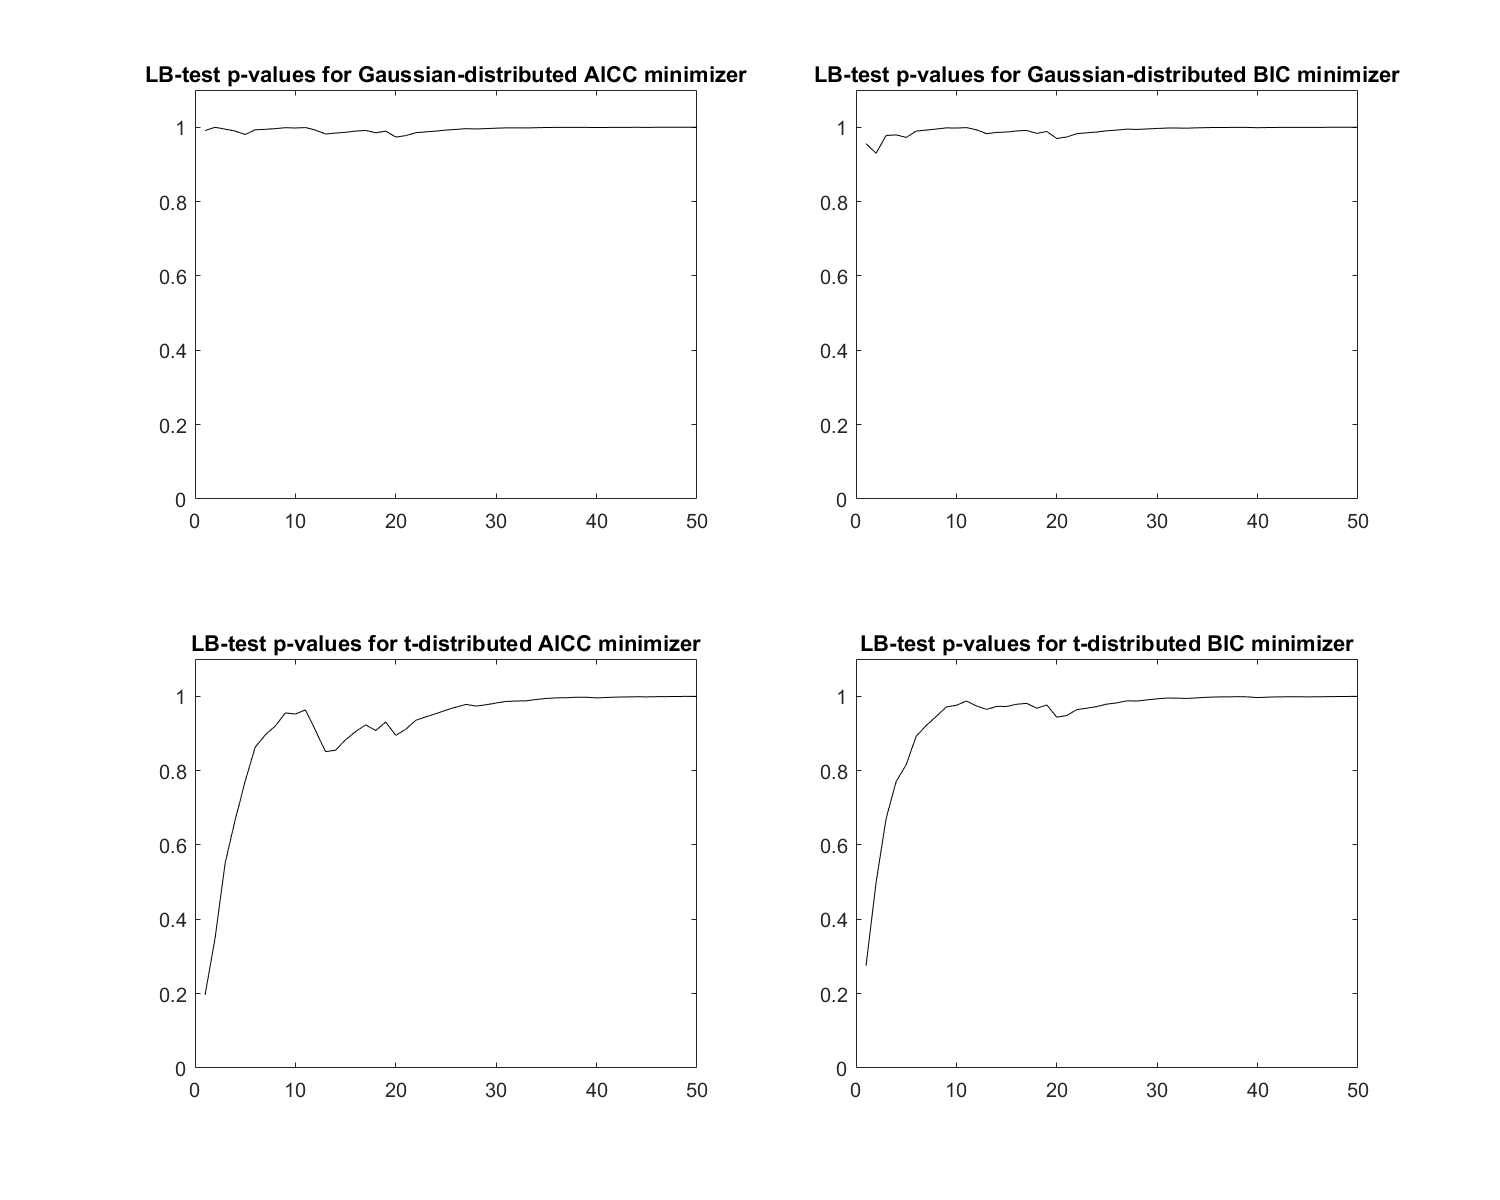

EstMdl_Gauss_AICC = estimate(bestmdl_Gauss_AICC, testX.^2,'Display','off'); % use X, trainX, testX here?
EstMdl_Gauss_BIC = estimate(bestmdl_Gauss_BIC, testX.^2, 'Display', 'off'); % getting [Warning: LOwer bound constraints are active; standard errors may be innacurate with] w/ Display on
EstMdl_t_AICC = estimate(bestmdl_t_AICC, testX.^2,'Display','off');
EstMdl_t_BIC = estimate(bestmdl_t_BIC, testX.^2,'Display','off');

[res_Gauss_AICC, v_Gauss_AICC] = infer(EstMdl_Gauss_AICC, testX.^2);
[res_Gauss_BIC, v_Gauss_BIC] = infer(EstMdl_Gauss_BIC, testX.^2);
[res_t_AICC, v_t_AICC] = infer(EstMdl_t_AICC, testX.^2);
[res_t_BIC, v_t_BIC] = infer(EstMdl_t_BIC, testX.^2);
res_Gauss_AICC = res_Gauss_AICC ./ sqrt(v_Gauss_AICC);
res_Gauss_BIC = res_Gauss_BIC ./ sqrt(v_Gauss_BIC);
res_t_AICC = res_t_AICC ./ sqrt(v_t_AICC);
res_t_BIC = res_t_BIC ./ sqrt(v_t_BIC);

lags = 1:50;
set(gcf,'Position',[100, 100, 1000, 800])
subplot(2,2,1)
[h, pValues, stat, cValue] = lbqtest(res_Gauss_AICC, 'lags', lags);
plot(lags, pValues, 'k')
ylim([0 1.1])
title('LB-test p-values for Gaussian-distributed AICC minimizer')

subplot(2,2,2)
[h, pValues, stat, cValue] = lbqtest(res_Gauss_BIC, 'lags', lags);
plot(lags, pValues, 'k')
ylim([0 1.1])
title('LB-test p-values for Gaussian-distributed BIC minimizer')

subplot(2,2,3)
[h, pValues, stat, cValue] = lbqtest(res_t_AICC, 'lags', lags);
plot(lags, pValues, 'k')
ylim([0 1.1])
title('LB-test p-values for t-distributed AICC minimizer')

subplot(2,2,4)
[h, pValues, stat, cValue] = lbqtest(res_t_BIC, 'lags', lags);
plot(lags, pValues, 'k')
ylim([0 1.1])
title('LB-test p-values for t-distributed BIC minimizer')

All p-values for Ljung-Box test up to h=50 are not statistically significant, so we do not reject any of the null hypotheses that the standardized residuals are IID noise.

@Matthias: Can you "deduce from the obtained ARMA models the orders of GARCH models that could be suitable to model the returns"?

% EstMdlG = estimate(bestmdlGaussian,X.^2)
% 
% [resG, v] = infer(EstMdlG, X.^2);
% sresG = resG./sqrt(v);
% autocorr(sresG,'NumLags',50)

% lags = 1:50;
% [h, pValues, stat, cValue] = lbqtest(sresG, 'lags', lags);
% p = plot(lags, pValues, 'k');
% ylim([0, 1.1])
% title('p-values for LGQ-test')

% EstMdlT = estimate(bestmdlT,X.^2)
% 
% [resT, v] = infer(EstMdlT, X.^2);
% sresT = resT./sqrt(v);
% autocorr(sresT,'NumLags',50)

% [h, pValues, stat, cValue] = lbqtest(sresT, 'lags', lags);
% p = plot(lags, pValues, 'k');
% ylim([0, 1.1])
% title('p-values for LGQ-test')

### 4)

Let $K$be the maximal order of the ARMA models with Gaussian noise fitted in the previous task. For all values of $p$ and $q$ such that $0<p\le K$ and $0\le q\le K,$ fit a $\textrm{GARCH}\left(p,q\right)$ process driven by Gaussian noise to the training data and compute the BIC and AICC (this will take a couple of minutes). Which models minimize the two information criteria? Write these candidate models down including the assumption on the noise.

clearvars EstMdl numParam_garch logL_garch
Options = optimoptions(@fmincon,'ConstraintTolerance',1e-7,'Algorithm','interior-point');
i=1;
K=3; %Need to choose a value according to the question
% @Matthias wouldnt this be 3? in my understanding its max(p,q)
qp_garch = [];
for p = 1:K
    for q = 1:K
        mdl_temp = garch(q,p); %did not work to put it in an array, so dont save the mdl
        [EstMdl(i), ~, logL_garch(i), ~] = estimate(mdl_temp, trainX, 'Display', 'off', 'Options', Options);
% @Matthias: "fit a GARCH process driven by Gaussian noise to the training
% data" that implies using trainX not trainX.^2 right? When I do trainX I get
% BIC minimizer of p=1,q=1 and the residual plot is nothing like that for
% AICC. I'm guessing we're supposed to use trainX.^2
        results = summarize(EstMdl(i));
        numParam_garch(i) = sum(results.Table.Value ~= 0); % = M from hints
        qp_garch = [qp_garch,  [q; p]];
        i = i + 1;
    end
end
q_garch = qp_garch(1,:);
p_garch = qp_garch(2,:);

AICC_garch = calculateAICC(length(trainX), numParam_garch, logL_garch); % both defined at end of file
BIC_garch = -2*logL_garch + numParam_garch*log(length(trainX));

%Might want to find something neater to find the minimum.
min_p_garch_AICC = p_garch(find(AICC_garch==min(AICC_garch)));
min_q_garch_AICC = q_garch(find(AICC_garch==min(AICC_garch)));
min_p_garch_BIC = p_garch(find(BIC_garch==min(BIC_garch)));
min_q_garch_BIC = q_garch(find(BIC_garch==min(BIC_garch)));

best_mdl_AICC = EstMdl(find(AICC_garch==min(AICC_garch)));
best_mdl_BIC = EstMdl(find(BIC_garch==min(BIC_garch)));
disp(["Model which minimizes [BD]'s AICC: p="+num2str(min_p_garch_AICC)+"  q="+num2str(min_q_garch_AICC); ...
    "Model which minimizes hint's BIC: p="+num2str(min_p_garch_BIC)+"  q="+num2str(min_q_garch_BIC)])

    "Model which minimizes [BD]'s AICC: p=2  q=2"
    "Model which minimizes hint's BIC: p=1  q=1"



[aic_garch, bic_garch, ic_garch] = aicbic(logL_garch, numParam_garch, length(trainX));
[~,minIdx_garch] = structfun(@min,ic_garch);

min_p_garch_AICC = p_garch(minIdx_garch(3));
min_q_garch_AICC = q_garch(minIdx_garch(3));
min_p_garch_BIC = p_garch(minIdx_garch(2));
min_q_garch_BIC = q_garch(minIdx_garch(2));

disp(["Model which minimizes aicbic's AICC: p="+num2str(min_p_garch_AICC)+"  q="+num2str(min_q_garch_AICC); ...
    "Model which minimizes aicbic's BIC: p="+num2str(min_p_garch_BIC)+"  q="+num2str(min_q_garch_BIC)])

    "Model which minimizes aicbic's AICC: p=2  q=2"
    "Model which minimizes aicbic's BIC: p=1  q=1"



### 5)

For the two identified candidate models that minimized the information criteria, perform a diagnostic check, i.e., compute the residuals and analyze these: What should the distribution and covariance structure of the residuals be if the model is correct? How does the autocorrelation plot of the residuals look like? How does the autocorrelation plot of the squared residuals look like? What about a qq-plot of the residuals? Are there problems? Finally, are the orders of your GARCH models coherent with the orders of the ARMA models obtained in Task 3?

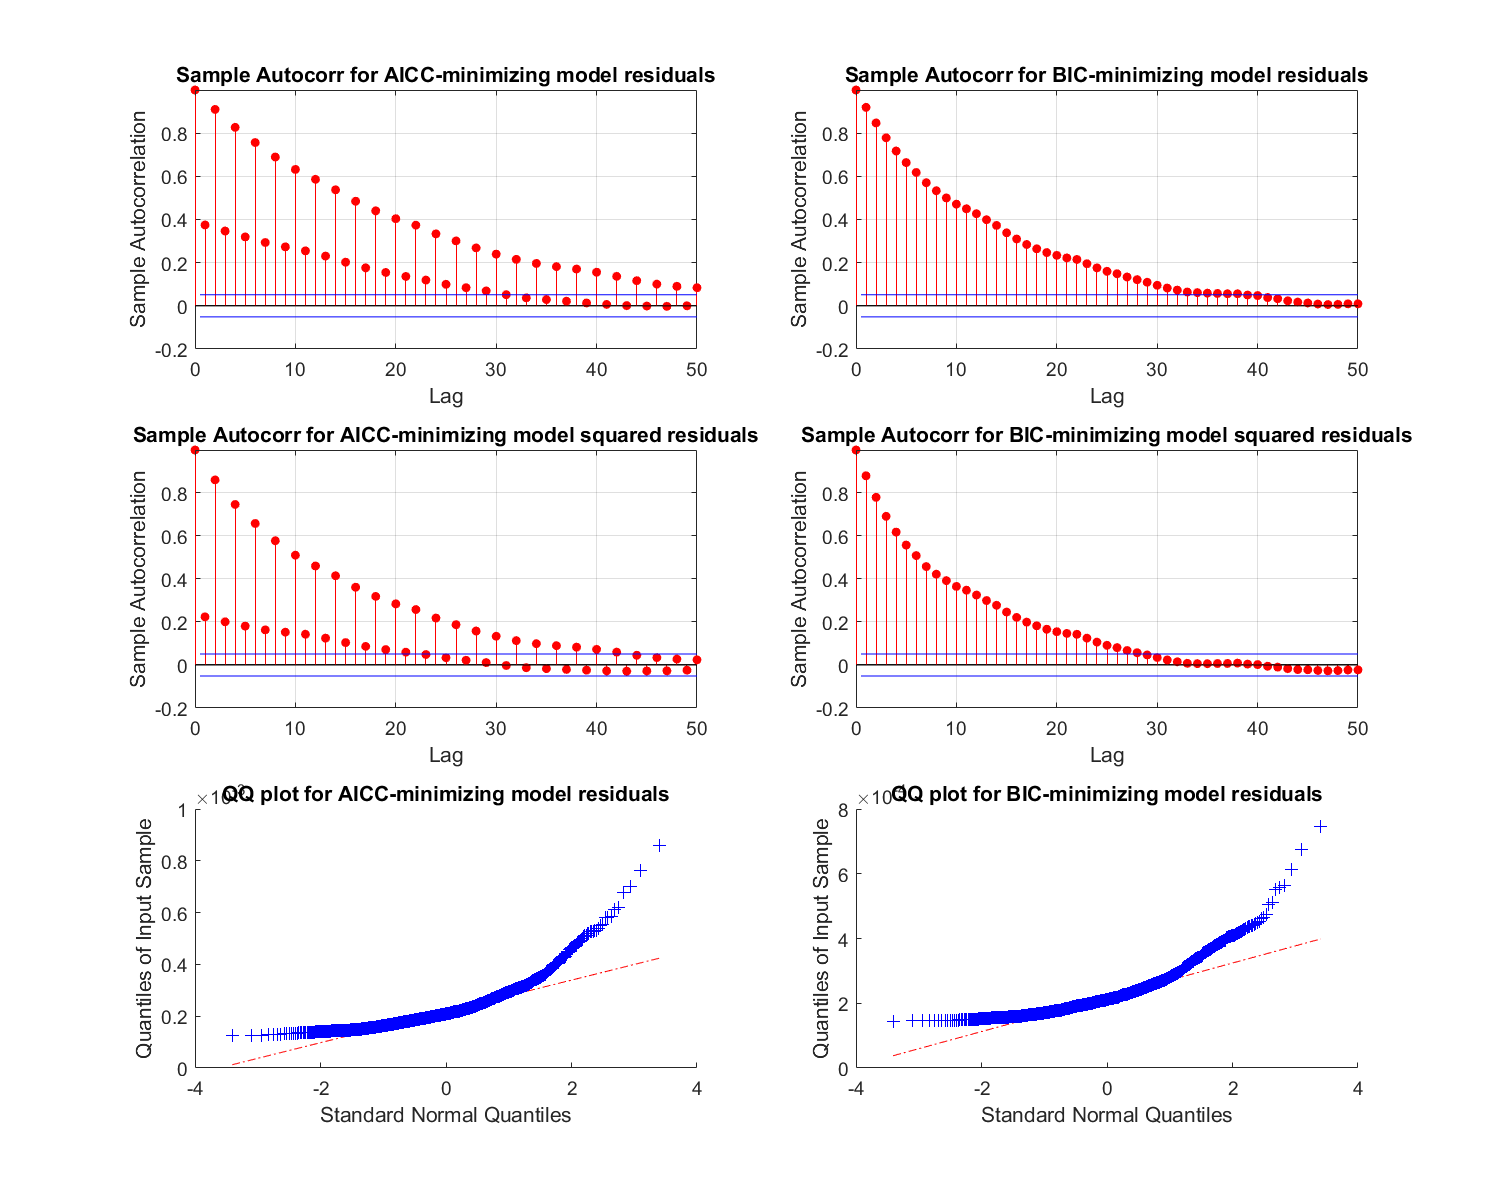

close all
set(gcf,'Position',[100, 100, 1000, 800])
[res_AICC, v_AICC] = infer(best_mdl_AICC,trainX);
[res_BIC, v_BIC] = infer(best_mdl_BIC,trainX);
subplot(3,2,1)
autocorr(res_AICC,50)
title('Sample Autocorr for AICC-minimizing model residuals')
subplot(3,2,3)
autocorr(res_AICC.^2,50)
title('Sample Autocorr for AICC-minimizing model squared residuals')
subplot(3,2,5)
qqplot(res_AICC)
title('QQ plot for AICC-minimizing model residuals')
subplot(3,2,2)
autocorr(res_BIC,50)
title('Sample Autocorr for BIC-minimizing model residuals')
subplot(3,2,4)
autocorr(res_BIC.^2,50)
title('Sample Autocorr for BIC-minimizing model squared residuals')
subplot(3,2,6)
qqplot(res_BIC)
title('QQ plot for BIC-minimizing model residuals')

The QQ-plots should follow a straight line if the residuals are normally distributed as we are fitting a GARCH process driven by Gaussian noise.

@Matthias: qqplot(trainX) has tails on either side, while qqplot(trainX.^2) looks like the qqplot(res_xyz) when the model is trained on trainX.^2  

### 6)

Repeat the previous two tasks, assuming now that the noise follows a *t*-distribution (and taking $K$ as the maximal order of the ARMA models with *t*-distribution noise fitted in Task 3), so that you end up with four candidate models.

### 7)

Estimate ${\textrm{VaR}}_t$ and evaluate the estimates for $t=1527,\ldotp \ldotp \ldotp ,1751$by following these steps for each of the four candidate models obtained in Tasks 4 and 6, as well as the four GARCH models obtained in Task 3:

- Report the distribution of $X_t$ given $\left(X_s ,V_s ,s<t\right)$ including its parameters (this will either be a Gaussian or a (generalized) *t*-distribution

- For each $t=1527,\ldotp \ldotp \ldotp ,1751$ of the test data set, compute ${\textrm{VaR}}_t$ given $\left(X_S ,V_s ,s<t\right)$ using (1) for $p=0\ldotp 1,0\ldotp 05,0\ldotp 01\ldotp$ Do not reestimate parameters of the models at each time $t,$ but use the observations $\left(X_2 ,\ldotp \ldotp \ldotp ,X_{t-1} \right)$ to update the conditional variances as needed

- Count the number of $\textrm{VaR}$ breaches, i.e., for $t=1577,\ldotp \ldotp \ldotp ,1751,$ count the number of times that $V_t -V_{t-1} \le {\textrm{VaR}}_t$

After doing this, also compute ${\textrm{VaR}}_t$ under the simple model that $X_t ~N\left(0,\hat{\;\sigma_{t-1}^2 } \right)$, where $\hat{\;\sigma_{t-1}^2 }$is the sample variance of $X_2 ,X_3 ,\ldotp \ldotp \ldotp ,X_{t-1}$ and count the number of breaches as above.

Report the number of breaches for each *p* and each of the candidate models. Based on the outcome of this experiment, what model for the estimation of ${\textrm{VaR}}_t$ would you recommend for this stock and why? (You are welcome to implement alternative models for the returns if you can find one that appears to fit the data better than the ones above. If so, you need to make a careful description of it and report your results in detail).

### Appendix: Functions

function AICC = calculateAICC(n, M, logL)
    factor = (2*n*M) ./ (n-M-1);
    AICC = -2*logL + factor;
end

function BIC = calculateBIC(n, p, q, var, X, M, which)
    if which == 'pq' % include zero-valued parameters
        left = (n-p-q) .* log( (n.*var) ./ (n-p-q) );
        middle = n * (1 + log(sqrt(2*pi)));
        right = (p+q) .* log((sum(X.^2) - n.*var) ./ (p+q)); % if n.*var is inside sum we get imaginary values?
        BIC = left + middle + right;
        
    else % do not include zero-valued parameters
        left = (n-M) .* log( (n.*var) ./ (n-M));
        middle = n * (1 + log(sqrt(2*pi)));
        right = M .* log((sum(X.^2) - n.*var) ./ M);
        BIC = left + middle + right;
    end
end